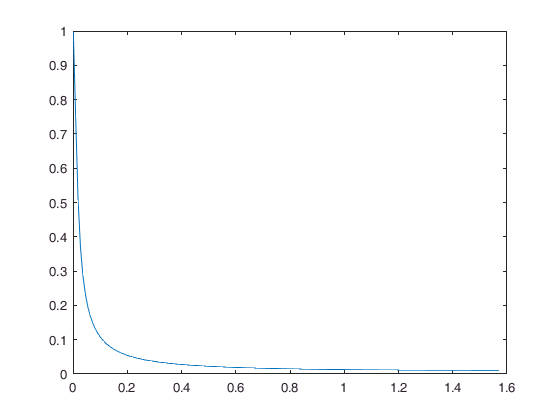

Z0 = 120*pi;
Y0 = 1/Z0;
phi = linspace(.001,pi/2,180);
er = 9.7 + 1i*.01;
kt = .0025;
Re = -1i*Z0/(kt*(er - 1));
Re_p = -1i*Y0*er/(kt*(er - 1));
R_pen = -1./(1 + 2*Re/Z0*sin(phi));
plot(phi,abs(R_pen))

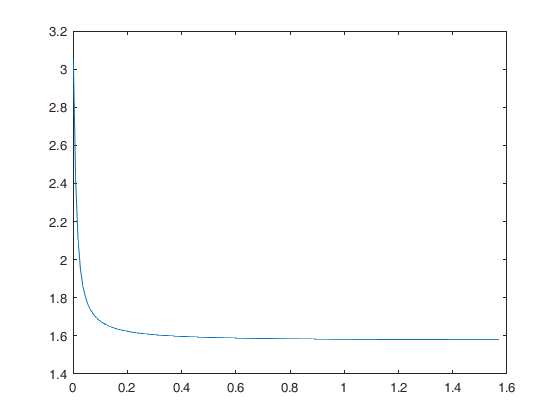

plot(phi, -angle(R_pen))

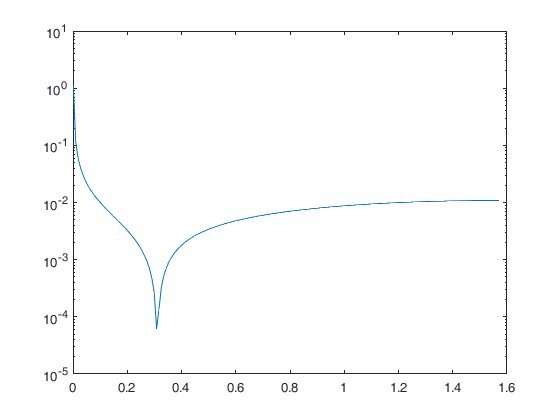

R_par = 1./(1 + 2*Re./(Z0*sin(phi))) - 1./(2*Re_p/Y0*sin(phi)./cos(phi).^2);
semilogy(phi, abs(R_par))

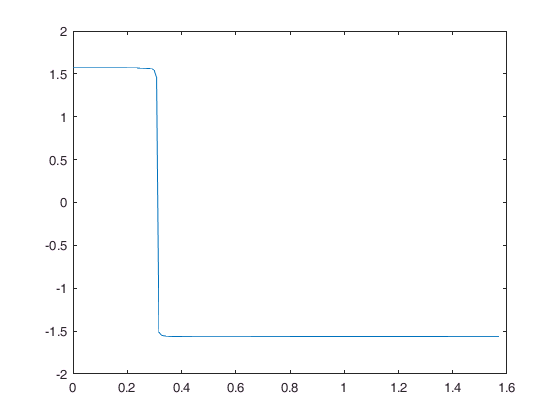

plot(phi,-angle(R_par))